% ------------------ Transmisión mediante AM de un tono puro (exponencial compleja) ------------------------------


% Paso 1 - Generar el tono puro a transmitir

% Parámetros para la Adalm Pluto
% - Rango de frecuencias 325 MHz a 3.8 GHz
% - Ancho de banda (muestreo) desde 200 kHz a 20 MHz

% Frecuencia de muestreo del transmisor (1 MHz).
% Frecuencia de la portadora (200 kHz)
% Frecuencia central de transmisión (915 MHz)
% Ganancia de transmisión
% Índice de modulación (entre 0 y 1)
fs_tx = 1e6; 
f_c = 200e3; 
frecuencia_RF = 915e6; 
ganancia = 0; 
indice_modulacion = 1; 

% Frecuencia del tono puro (1 kHz)
% Duración del tono en segundos
f_m = 1e3;  
duracion = 0.01; 

% Vector de tiempo (Potencial problema: vector excesivamente largo al usar
% 1MHz como fs_tx). Posible solución: disminuir mucho la duración del tono.
t_tx = (0:1/fs_tx:duracion-1/fs_tx); 

% Generar el tono puro (señal moduladora). Está normalizado, sino, sería
% necesario devidir entre su máximo.
tono_puro = cos(2 * pi * f_m * t_tx);

% Paso 2 - Configuración de la transmisión AM

% Señal portadora
portadora = exp(2 * pi * f_c * i * t_tx);

% Señal modulada en AM: (1 + m(t)) * cos(2*pi*fc*t)
am_modulada = (1 + indice_modulacion * tono_puro) .* portadora;
am_modulada_norm = am_modulada/max(am_modulada);

% Figura 1: Señal Modulada en AM (Representación Temporal)
figure
plot(t_tx, am_modulada_norm);

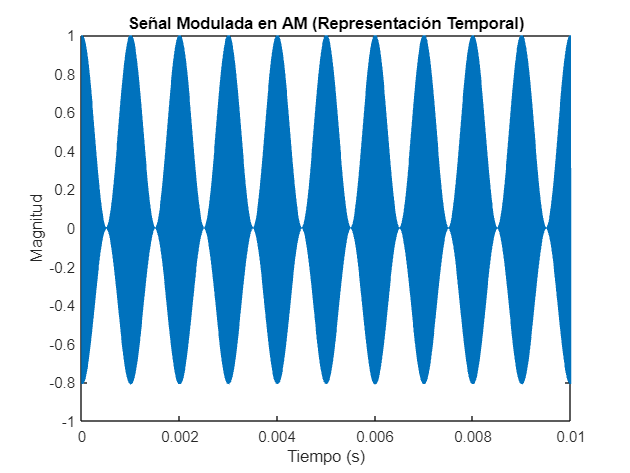

xlim([0 0.01])
title('Señal Modulada en AM (Representación Temporal)');
xlabel('Tiempo (s)');
ylabel('Magnitud');

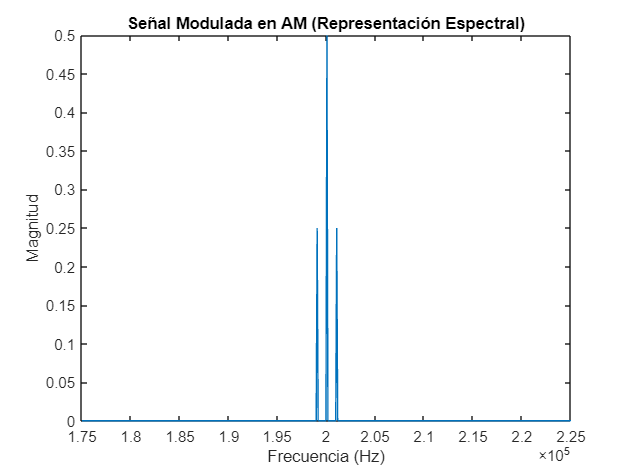

% Figura 2: Señal Modulada en AM (Representación Espectral)
fft_modulada_norm = fftshift(abs(fft(am_modulada_norm, length(am_modulada_norm)))/length(am_modulada_norm)); 
fft_axis_modulada_norm = linspace(-fs_tx/2, fs_tx/2, length(am_modulada_norm));
figure 
plot(fft_axis_modulada_norm, abs(fft_modulada_norm))
xlim([1.75e5 2.25e5])
title('Señal Modulada en AM (Representación Espectral)');
xlabel('Frecuencia (Hz)');
ylabel('Magnitud');

% Paso 3: Configurar el transmisor PlutoSDR y transmitir

% Crear objeto transmisor PlutoSDR
tx = sdrtx('Pluto');

% Crear el objeto Receptor.
rx = sdrrx('Pluto');

% Frecuencia central de transmisión
tx.CenterFrequency = frecuencia_RF; 

% Frecuencia de muestreo
tx.BasebandSampleRate = fs_tx; 
rx.BasebandSampleRate = fs_tx;

% Ganancia de transmisión
tx.Gain = ganancia; 

% Transmitir el tono modulado en AM
tx.transmitRepeat(am_modulada_norm.');

## Establishing connection to hardware. This process can take several seconds.
## Waveform transmission has started successfully and will repeat indefinitely. 
## Call the release method to stop the transmission.


% Calcular cuantos segundos de la señal corresponden a una trama recibida.
% Con la configuración por defecto, esto es 20.000 muestras por trama entre
% 1.000.000 que es la f_tx. Es decir 0.02 segundos por trama. Otra
% alternativa es dejarlo un tiempo arbitrario suficientemente largo para
% que le de tiempo a transmitir.

segundos_por_trama = rx.SamplesPerFrame / rx.BasebandSampleRate;

% Como conocemos la duración, escogemos que el número de tramas sea 0.01/0.02 = 0.5. Aproximamos a 1. Si no
% conocieramos la duración, usaríamos un valor de tramas arbitrario.

% Vector para almacenar las muestras
[datos, datosInvalidos, overflow] = rx(); 

## Establishing connection to hardware. This process can take several seconds.



% Comprobar el overflow de las muestras recibidas.
if (overflow) % Se han perdido muestras
    disp('samples dropped');
end

% Comprobar, si no hay overflow, que las muestras son válidas
if ~(overflow) % No ha habido overflow
    if (datosInvalidos) % Los datos recibidos son inválidos
        disp('no valid data received');
    end
end

no valid data received


% Para detener la transmisión:
release(tx)
release(rx)

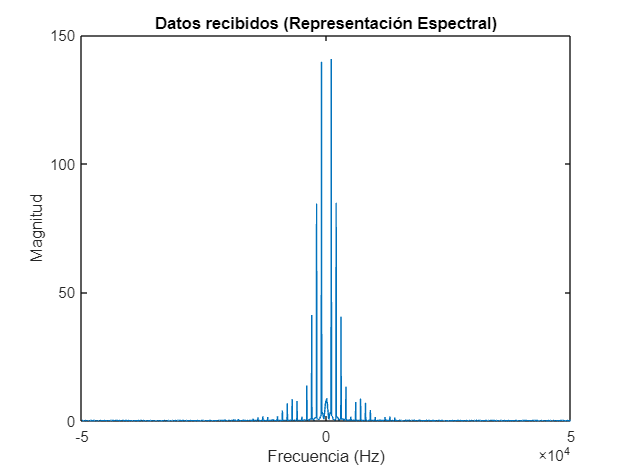

% Paso 4: Procesado de la señal recibida

% Visualizar los datos recibidos. Se convierte la señal a double para que
% se pueda procesar la señal recibida.
datos_procesables = double(datos);

% Pendiente de revisar: error de longitud de vectores
% ----------------------------------------------------

% Figura 3: Datos recibidos de la transmisión (Tiempo)

% figure;
% tiempo_procesado = (0 : 1/fs_tx : length(datos_procesables)-1/fs_tx); 
% plot(tiempo_procesado, datos_procesables);
% xlabel('Tiempo (s)');
% ylabel('Amplitud');
% title('Datos recibidos (Representación Temporal)'); 

% Figura 4: Datos recibidos de la transmisión (Espectro)
fft_datos_received = fftshift(abs(fft(datos_procesables, length(datos_procesables)))/length(datos_procesables)); 
fft_axis_datos_received = linspace(-fs_tx/2, fs_tx/2, length(datos_procesables));
figure 
plot(fft_axis_datos_received, abs(fft_datos_received)) 
xlim([-0.5e5, 0.5e5])
title('Datos recibidos (Representación Espectral)');
xlabel('Frecuencia (Hz)');
ylabel('Magnitud');

% Portadora a una frecuencia de -f_c
portadora_recepcion =  exp(2 * pi * -f_c * 1i * t_tx);

% PRUEBA 1: Demodular la señal "toda de golpe". Error de tamaños de
% vectores.

% Demodular la señal
signal_recibida = datos_procesables .* portadora_recepcion;

% Obtener la envolvente de la señal
envolvente = abs(signal_recibida);

% Se emplea un condensasdor, ya que no es necesario un filtrado por la modulación con la exponencial compleja. 
% Eliminar la componente continua
signal_demodulada = envolvente - mean(envolvente); 

% -----------------------------------------------------------------------------------------------------------

% PRUEBA 2: Demodulación de la señal recibida por bloques de 100. Matlab se
% queda colgado
% bloque = 100;

% Inicializar la señal demodulada
% signal_demodulada = [];

% Pendiente de revisar. No se puede ejecutar porque se queda colgado el ordenador
% -------------------------------------------------------------------------------
% for i = 1:bloque
    % Calcular los índices para el bloque actual
    % indice_inicial = (i - 1) * bloque + 1;
    % indice_final = min(i * bloque, size(datos_procesables, 1));

    % Extraer una submatriz de datos 
    % Multiplicación con la portadora
    % Obtener la envolvente
    % Eliminar la componente continua

    % submatriz_datos = datos_procesables(indice_inicial:indice_final, :); 
    % submatriz_signal_recibida = submatriz_datos .* portadora_recepcion;  
    % submatriz_envolvente = abs(submatriz_signal_recibida);              
    % submatriz_demodulada = submatriz_envolvente - mean(submatriz_envolvente);  

    % Concatenar los resultados de cada bloque
    % signal_demodulada = [signal_demodulada; submatriz_demodulada];
% end

% Paso 5: Análisis de resultados

% Figura 5: Espectro de la señal Demodulada
fft_datos_demodulada = fftshift(abs(fft(signal_demodulada, length(signal_demodulada))) / length(signal_demodulada));
fft_axis_demodulada = linspace(-fs_tx/2, fs_tx/2, length(signal_demodulada));

figure;
plot(fft_axis_demodulada, abs(fft_datos_demodulada));
xlabel('Frecuencia (Hz)');
ylabel('Magnitud');
title('Espectro de la señal demodulada');